# E4

## Binarització 

### Binarització global

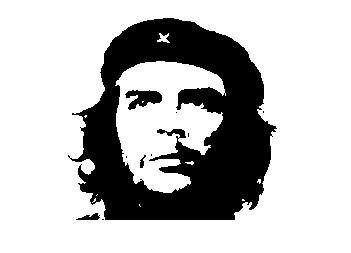

I = imread('Che.jpg');
I = rgb2gray(I);
llindar = 90;
BW = I > llindar;
imshow(BW);

### Binarització dos llindars

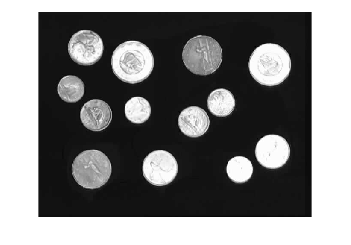

I = imread('money.tif');
imshow(I);

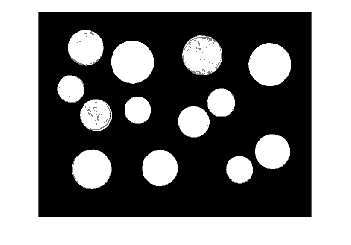

H = I > 128;
L = I < 64;
M = H == L;
R = H*2 + M;
imshow(R, [])

### Binarització per area

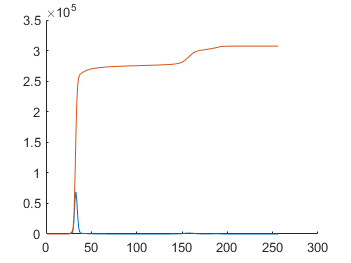

I = rgb2gray(imread('Blispac2.tif'));
imshow(I);
nPixels1 = 30000;
nPixels1Actual = 0;

h = imhist(I);
hacum = cumsum(h);
figure
hold on
plot(h);
plot(hacum);
hold off;

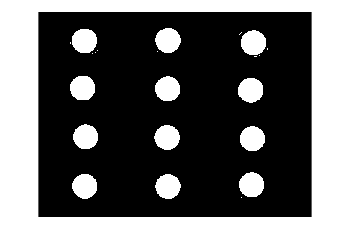


[f, c] = size(I);
area = 12 * (28.5^2 * pi);
valor = f*c - area;
cum = 0;

for i = 0; (i < size(hacum)); i = i + 1;
    cum = cum + cumsum(i);
    if cum >= valor
        llindar = i;
        break;
    end
end
J = (I > llindar);
imshow(J);

sum(sum(J))

ans = 32341


% Amb funcio matlab
bhacum = hacum > valor;
llindar = find(bhacum, 1)

llindar = 128

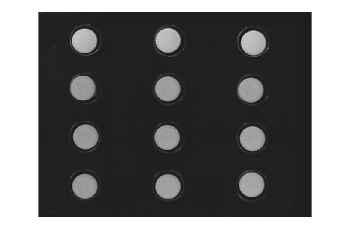

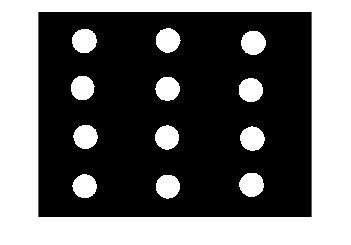

imshow(I > llindar)

### Otsu Thresholding

I = rgb2gray(imread('Blispac2.tif'));
h = imhist(I);
total = sum(h);
w1 = 0; m1 = 0;
P = 0;
maxvar = 0; tmax = 0;
% Calculem meanT
meanT = 0;
for i = 1:255
        meanT = meanT + i*h(i)/total;
end

for t = 1:255
    p = h(t)/total;
    w1 = w1 + p;
    w2 = 1 - w1;
    P = P + t*p;
    m1 = P/w1;
    m2 = (meanT - w1*m1)/w2;
    varb2 = w1*w2*(m1 - m2)^2;
    if (varb2 > maxvar)
        maxvar = varb2;
        tmax = t;
    end
end
tmax

tmax = 97

maxvar

maxvar = 1.4894e+03

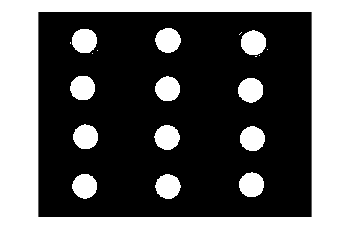


%% Amb funció de MATLAB
level = 255*graythresh(I);
BW = I > level;
imshow(BW)

### Labelling

C = bwconncomp(BW)

C = struct with fields:
    Connectivity: 8
       ImageSize: [480 640]
      NumObjects: 20
    PixelIdxList: {1×20 cell}
